## 1.1 Impulse responses, transfer functions

We are given this impulse response of running sum filter of order N:

We wil calculate the poles and zeros for N = 3 and N = 5.

#### N = 3:

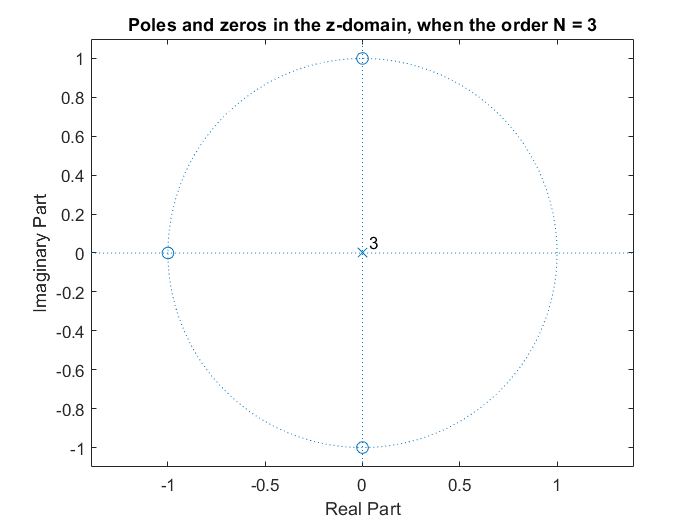

%We do the z-transformation for 3. order:
num = [1 1 1 1];
den = [1 0 0 0];

poles = roots(den);
zeros = roots(num);

%We plot the poles and zeros in the z-domain:
figure(1)
zplane(zeros, poles)
title('Poles and zeros in the z-domain, when the order N = 3')

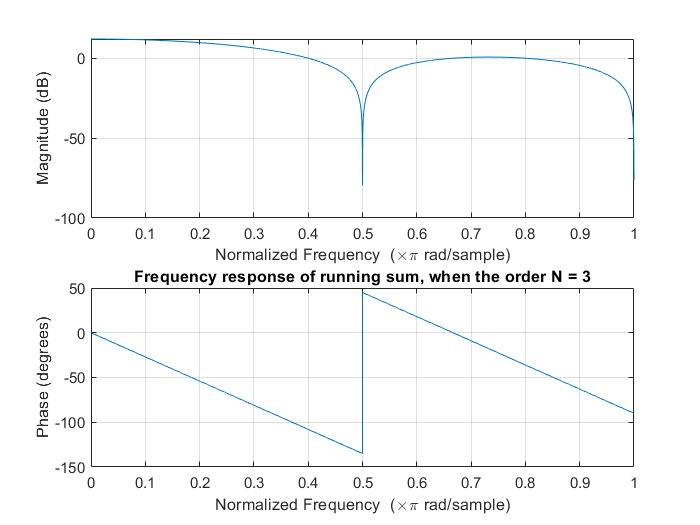


%We plot the frequency response:
figure(2)
freqz(num,den,42069)
title('Frequency response of running sum, when the order N = 3')

#### N = 5:

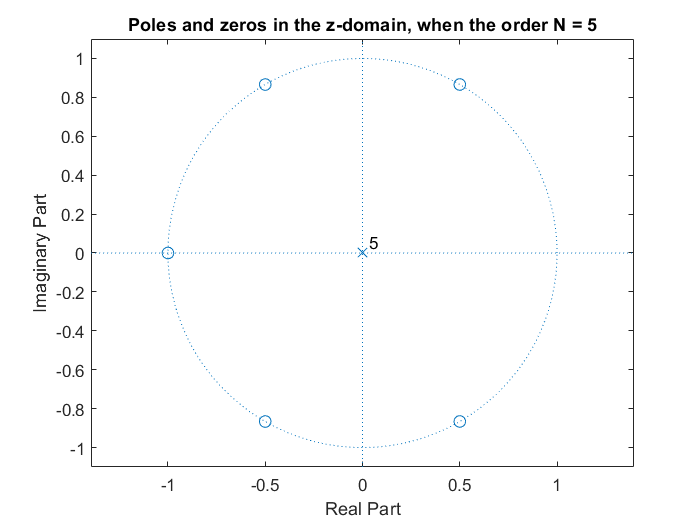

%We do the z-transformation for 5. order:
num2 = [1 1 1 1 1 1];
den2 = [1 0 0 0 0 0];

poles2 = roots(den2);
zeros2 = roots(num2);

figure(3)
zplane(zeros2, poles2)
title('Poles and zeros in the z-domain, when the order N = 5')

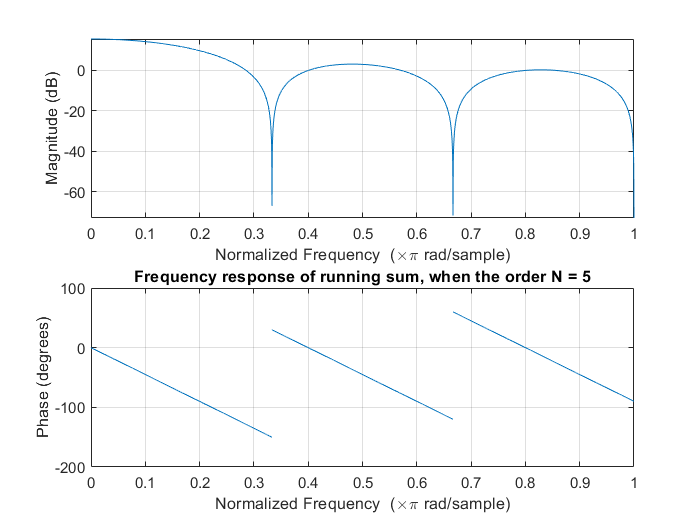


figure(4)
freqz(num2, den2, 42069)
title('Frequency response of running sum, when the order N = 5')

What happens to the frequency response when considering a moving average rather than a running sum?

#### N = 3:

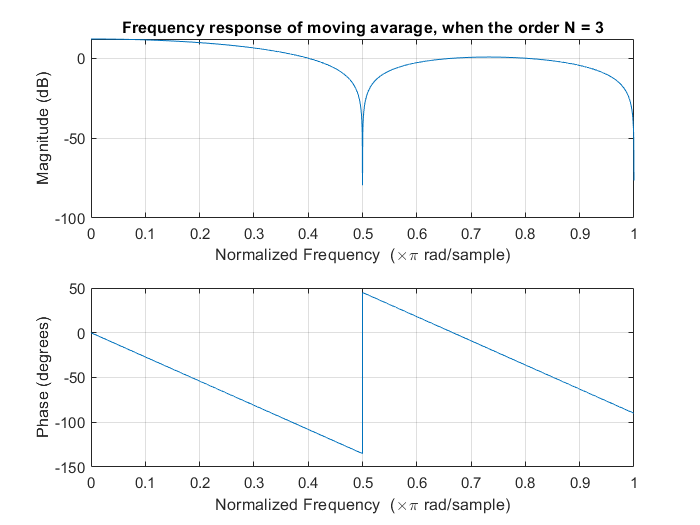

N = 3;
num_MA = (num)/(N+1);
den_MA = (den)/(N+1);

freqz(num_MA, den_MA, 42069)
title('Frequency response of moving avarage, when the order N = 3')

#### N = 5:

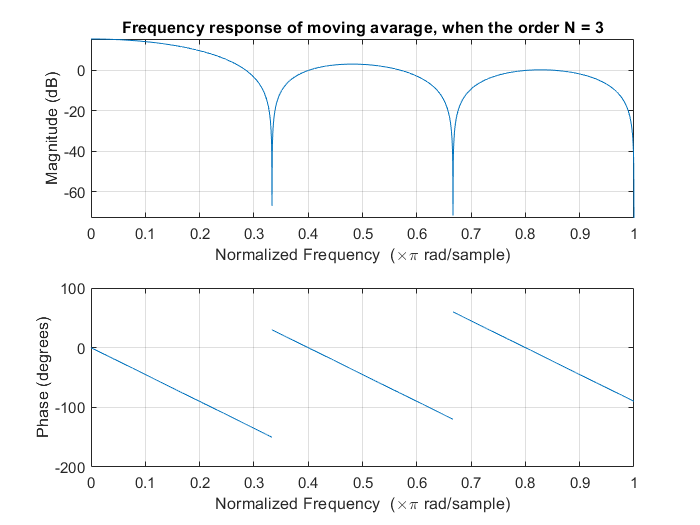

N2 = 5;
num_MA2 = (num2)/(N2+1);
den_MA2 = (den2)/(N2+1);

freqz(num_MA2, den_MA2, 42069)
title('Frequency response of moving avarage, when the order N = 3')


%No visible difference in the plots.

Some frequencies are heavily suppressed (attenuated) in these filters. Is there a simple way to enhance (that means to amplify) these frequencies rather than to attenuate them?

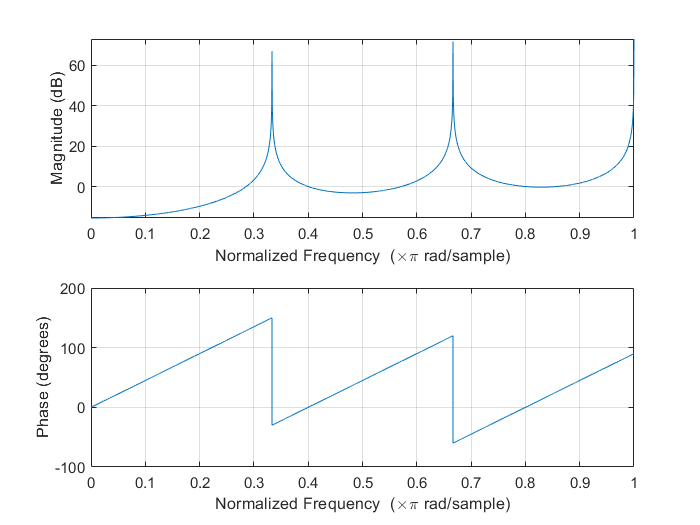

%Lets try and swap the zeros and poles:
freqz(den_MA2, num_MA2, 42069)

%This works. Great.

Design a filter that blocks the normalized frequency of 0.1 by placing 4 zeros in the z-plane. Make sure the filter returns real-values outputs when fed with real-valued inputs by placing complex-conjugate pairs of poles and zeros.